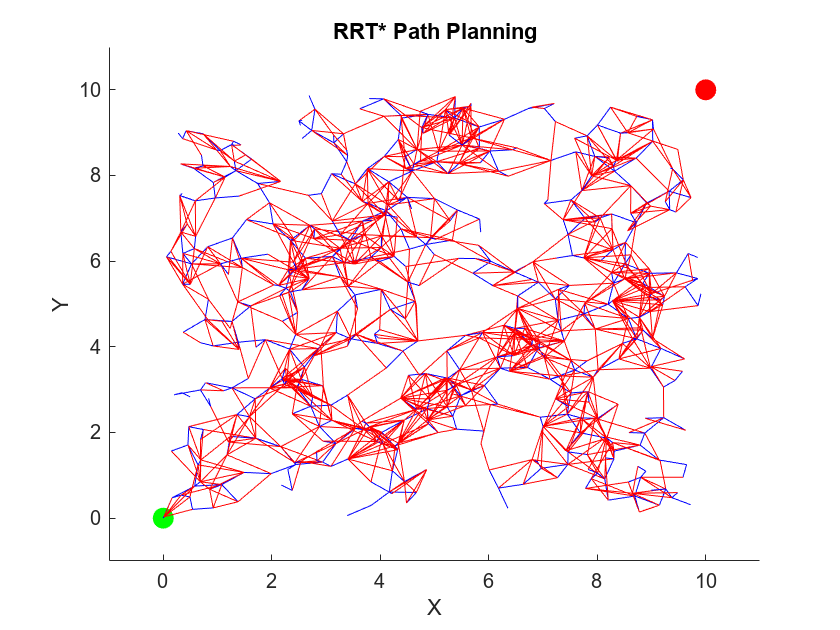

% Parametri di configurazione

start_pos = [0, 0];
goal_pos = [5, 5];
max_iterations = 1000;
step_size = 0.5;
goal_threshold = 0.5;

% Inizializzazione
tree.vertices = start_pos;
tree.edges = [];
goal_reached = false;

% Visualizzazione iniziale
figure;
hold on;
plot(start_pos(1), start_pos(2), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
plot(goal_pos(1), goal_pos(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlim([-1, 11]);
ylim([-1, 11]);
title('RRT Path Planning');
xlabel('X');
ylabel('Y');

% Loop principale
for iter = 1:max_iterations
    % Genera un punto casuale
    rand_point = [rand * 10, rand * 10];

    % Trova il nodo più vicino nel grafo
    distances = vecnorm(tree.vertices - rand_point, 2, 2);
    [~, nearest_index] = min(distances);
    nearest_vertex = tree.vertices(nearest_index, :);

    % Calcola il nuovo punto in direzione del punto casuale
    direction = rand_point - nearest_vertex;
    distance = norm(direction);
    if distance < step_size
        new_point = rand_point;
    else
        new_point = nearest_vertex + step_size * (direction / distance);
    end

    % Aggiungi il nuovo punto al grafo
    tree.vertices = [tree.vertices; new_point];
    tree.edges = [tree.edges; nearest_index, size(tree.vertices, 1)];

    % Visualizza il nuovo segmento dell'albero
    plot([nearest_vertex(1), new_point(1)], [nearest_vertex(2), new_point(2)], 'b');
    drawnow;

    % Controlla se il goal è raggiunto
    if norm(new_point - goal_pos) < goal_threshold
        goal_reached = true;
        disp('Goal raggiunto!');
        break;
    end
end

if ~goal_reached
    disp('Goal non raggiunto, massimo numero di iterazioni superato');
end
